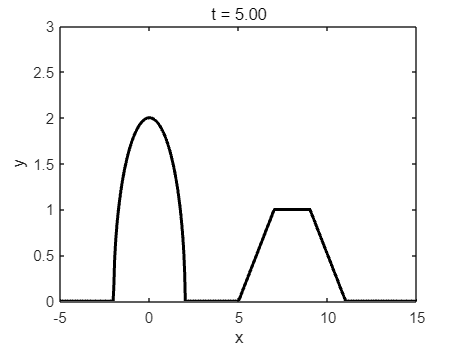

clear; clc; close all;

% 梯形孤波参数
h_t = 1; % 梯形高度
leftX_t = 2; % 左斜边水平投影
rightX_t = 2; % 右斜边水平投影
top_t = 2; % 顶部宽度
center_t_0 = 0; % 初始左侧位置
v_t = 1; % 梯形速度
% 椭圆孤波参数
h_e = 2; % 椭圆高度
width = 2; % 椭圆宽度
center_e_0 = 10; % 初始中心位置
v_e = -2; % 椭圆速度

x = linspace(-5, 15, 500);
t_list = linspace(0, 5, 100);

figure;
for ti = 1:length(t_list)
    t = t_list(ti);

    % 梯形孤波位置
    x_left = center_t_0 + v_t*t;  % 最左点
    x1 = x_left;
    x2 = x1 + leftX_t; % 左斜边顶点
    x3 = x2 + top_t; % 右斜边顶点
    x4 = x3 + rightX_t; % 最右点

    % 分段定义梯形
    trap = zeros(size(x));
    for i = 1:length(x)
        if x(i) >= x1 && x(i) < x2
            trap(i) = h_t*(x(i)-x1)/leftX_t;       
        elseif x(i) >= x2 && x(i) <= x3
            trap(i) = h_t;                         
        elseif x(i) > x3 && x(i) <= x4
            trap(i) = h_t*(x4-x(i))/rightX_t;      
        else
            trap(i) = 0;                           
        end
    end

    %-------------------------
    % 椭圆孤波位置（上半椭圆）
    center_e = center_e_0 + v_e*t;
    ellipse = zeros(size(x));
    for i = 1:length(x)
        dx = (x(i)-center_e)/width;
        if abs(dx) <= 1
            ellipse(i) = h_e*sqrt(1 - dx^2);
        else
            ellipse(i) = 0;
        end
    end

    %-------------------------
    % 总叠加
    total = trap + ellipse;

    %-------------------------
    % 绘图
    plot(x, total, 'k', 'LineWidth', 2);
    hold off;

    ylim([0, max(h_t,h_e)*1.5]);
    xlim([-5, 15]);
    title(sprintf('t = %.2f', t));
    xlabel('x'); ylabel('y');
    drawnow;
end